M_set = 65;          % % substrate moisture (example optimal)
M_measured = 52;     % current reading

eM = M_set - M_measured;


fisP = mamfis('Name','SubstrateMoisturePumpController');


fisP = addInput(fisP, [-40 40], 'Name', 'MoistureError');

fisP = addMF(fisP, 'MoistureError', 'trimf', [-40 -40 0], 'Name', 'Wet');
fisP = addMF(fisP, 'MoistureError', 'trimf', [-10 0 10], 'Name', 'OK');
fisP = addMF(fisP, 'MoistureError', 'trimf', [0 40 40], 'Name', 'Dry');

fisP = addOutput(fisP, [0 100], 'Name', 'PumpLevel');

fisP = addMF(fisP, 'PumpLevel', 'trimf', [0 0 20],   'Name', 'OFF');
fisP = addMF(fisP, 'PumpLevel', 'trimf', [15 35 55], 'Name', 'LOW');
fisP = addMF(fisP, 'PumpLevel', 'trimf', [50 75 100],'Name', 'HIGH');

rulesP = [
    "IF MoistureError IS Wet THEN PumpLevel IS OFF"
    "IF MoistureError IS OK THEN PumpLevel IS OFF"
    "IF MoistureError IS Dry THEN PumpLevel IS HIGH"
];

fisP = addRule(fisP, rulesP);
    

pump_output = evalfis(fisP, eM)

pump_output = 75.0000

PWM_pump = round((pump_output / 100) * 255);

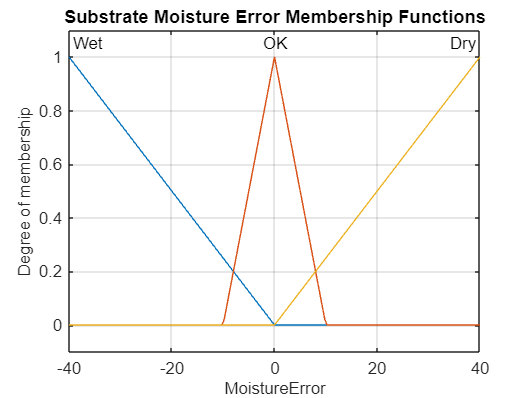

figure;
plotmf(fisP, 'input', 1)
title('Substrate Moisture Error Membership Functions')
grid on

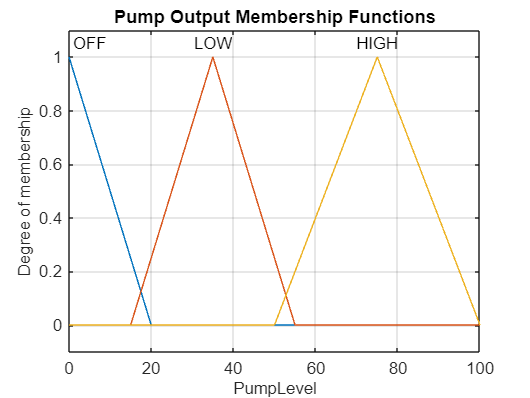

  
figure;
plotmf(fisP, 'output', 1)
title('Pump Output Membership Functions')
grid on

testMoisture = [40 55 65 75 85];  % %

disp('Moisture  Pump%  PWM')

Moisture  Pump%  PWM



for i = 1:length(testMoisture)
    M_measured = testMoisture(i);
    eM = M_set - M_measured;

    out = evalfis(fisP, eM);
    pwm = round((out / 100) * 255);

    fprintf('%6.0f   %6.2f   %3d\n', M_measured, out, pwm);
end

    40    75.00   191
    55    75.00   191
    65     6.33    16
    75     8.56    22
    85     7.52    19


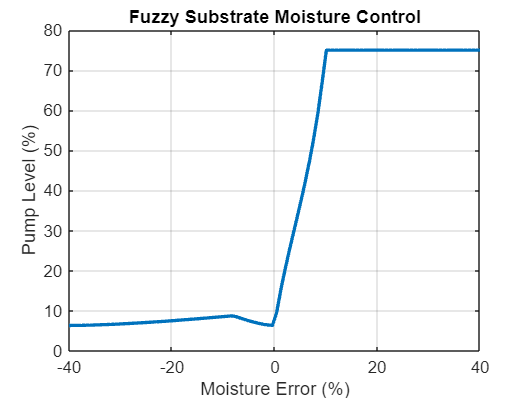

e_range = linspace(-40,40,100);
pump_level = zeros(size(e_range));

for i = 1:length(e_range)
    pump_level(i) = evalfis(fisP, e_range(i));
end

figure;
plot(e_range, pump_level, 'LineWidth', 2)
grid on
xlabel('Moisture Error (%)')
ylabel('Pump Level (%)')
title('Fuzzy Substrate Moisture Control')